
$$Here is the representation of Euler's formulae for the Fourier coefficients of a function \(f(x)\) and the Fourier series representation of \(f(x)\):

\(a_0 = \frac{1}{\pi} \int_{-\pi}^{\pi} f(x) dx\)

\(a_n = \frac{1}{\pi} \int_{-\pi}^{\pi} f(x) \cos(nx) dx\)

\(b_n = \frac{1}{\pi} \int_{-\pi}^{\pi} f(x) \sin(nx) dx\)

The coefficients can be used to represent \(f(x)\) as a Fourier series:

\[f(x) = \frac{a_0}{2} + \sum_{n=1}^{\infty} [a_n \cos(nx) + b_n \sin(nx)]\]

Where \(\Sigma\) denotes the summation symbol.$$



% Clear the workspace and command window
clear;
clc;


% Define the symbolic variable x and pi
syms x;

% Define the function f(x)
%f = exp(-x)
%f = x*sin(x)
f = x-x^2

$$f = x-x^{2}$$



% limits of integration
% L = 0;
% U = 2*pi;
L = -pi;
U = pi;

disp('lower bound/limit')

lower bound/limit


lb = sym(L) %lower bound/limit

$$lb = -\pi$$

disp('upper bound/limit')

upper bound/limit


ub = sym(U) %upper bound/limit

$$ub = \pi$$


disp('Define the number of terms in the Fourier series (n)')

Define the number of terms in the Fourier series (n)


n = 6  % Change this value as desired

n =      6




% Calculate the Fourier coefficients
disp('a0 = ')

a0 = 


a000 = (1/sym(pi)) * int(f, x, lb, ub,'Hold',true);
disp(a000)

$$\frac{\int_{-\pi }^{\pi }\left(x-x^{2}\right)\mathrm{d}x}{\pi }$$

a00 = (1/sym(pi)) * int(f, x);
disp(a00)

$$-\frac{x^{2}\,\left(2\,x-3\right)}{6\,\pi }$$

disp("Substituting the Limits of integration We get")

Substituting the Limits of integration We get


a0=release(a000);
disp(a0)

$$-\frac{2\,\pi^{2}}{3}$$

ann = sym('an', [1 n]); % function
an= sym('an', [1 n]);  % evaluted the integral
a = sym('a', [1 n]);   % after substuting the limits

bnn = sym('bn', [1 n]);
bn = sym('bn', [1 n]);
b = sym('b', [1 n]);

for k = 1:n

    fprintf('a%d = \n',k)


    ann(k) = (1/sym(pi)) * int(f*cos(k*x), x, lb, ub,'Hold',true);
    disp(ann(k))
    an(k) = (1/sym(pi)) * int(f*cos(k*x), x);
    disp(an(k))
    disp("Substituting the Limits of integration We get")
    a(k)=release(ann(k));
   
    disp(a(k))

    disp('---------------------------------------------------------------------------') 

    fprintf('b%d = \n',k)
 
    bnn(k) = (1/sym(pi)) * int(f*sin(k*x), x, lb, ub,'Hold',true);
    disp(bnn(k))
    bn(k) = (1/sym(pi)) * int(f*sin(k*x), x);
    disp(bn(k))
    b(k)=release(bnn(k));
    disp("Substituting the Limits of integration ")
    disp(b(k))

    disp('*************************************************************************')
end

a1 = 


$$\frac{\int_{-\pi }^{\pi }\cos\left(x\right)\,\left(x-x^{2}\right)\mathrm{d}x}{\pi }$$

$$\frac{\cos\left(x\right)+2\,\sin\left(x\right)-x^{2}\,\sin\left(x\right)-2\,x\,\cos\left(x\right)+x\,\sin\left(x\right)}{\pi }$$

Substituting the Limits of integration We get


$$4$$

---------------------------------------------------------------------------


b1 = 


$$\frac{\int_{-\pi }^{\pi }\sin\left(x\right)\,\left(x-x^{2}\right)\mathrm{d}x}{\pi }$$

$$-\frac{2\,\cos\left(x\right)-\sin\left(x\right)-x^{2}\,\cos\left(x\right)+x\,\cos\left(x\right)+2\,x\,\sin\left(x\right)}{\pi }$$

Substituting the Limits of integration 


$$2$$

*************************************************************************


a2 = 


$$\frac{\int_{-\pi }^{\pi }\cos\left(2\,x\right)\,\left(x-x^{2}\right)\mathrm{d}x}{\pi }$$

$$\frac{\frac{\cos\left(2\,x\right)}{4}+\frac{\sin\left(2\,x\right)}{4}-\frac{x\,\cos\left(2\,x\right)}{2}+\frac{x\,\sin\left(2\,x\right)}{2}-\frac{x^{2}\,\sin\left(2\,x\right)}{2}}{\pi }$$

Substituting the Limits of integration We get


$$-1$$

---------------------------------------------------------------------------


b2 = 


$$\frac{\int_{-\pi }^{\pi }\sin\left(2\,x\right)\,\left(x-x^{2}\right)\mathrm{d}x}{\pi }$$

$$-\frac{\frac{\cos\left(2\,x\right)}{4}-\frac{\sin\left(2\,x\right)}{4}+\frac{x\,\cos\left(2\,x\right)}{2}+\frac{x\,\sin\left(2\,x\right)}{2}-\frac{x^{2}\,\cos\left(2\,x\right)}{2}}{\pi }$$

Substituting the Limits of integration 


$$-1$$

*************************************************************************


a3 = 


$$\frac{\int_{-\pi }^{\pi }\cos\left(3\,x\right)\,\left(x-x^{2}\right)\mathrm{d}x}{\pi }$$

$$\frac{\frac{\cos\left(3\,x\right)}{9}+\frac{2\,\sin\left(3\,x\right)}{27}-\frac{2\,x\,\cos\left(3\,x\right)}{9}+\frac{x\,\sin\left(3\,x\right)}{3}-\frac{x^{2}\,\sin\left(3\,x\right)}{3}}{\pi }$$

Substituting the Limits of integration We get


$$\frac{4}{9}$$

---------------------------------------------------------------------------


b3 = 


$$\frac{\int_{-\pi }^{\pi }\sin\left(3\,x\right)\,\left(x-x^{2}\right)\mathrm{d}x}{\pi }$$

$$-\frac{\frac{2\,\cos\left(3\,x\right)}{27}-\frac{\sin\left(3\,x\right)}{9}+\frac{x\,\cos\left(3\,x\right)}{3}+\frac{2\,x\,\sin\left(3\,x\right)}{9}-\frac{x^{2}\,\cos\left(3\,x\right)}{3}}{\pi }$$

Substituting the Limits of integration 


$$\frac{2}{3}$$

*************************************************************************


a4 = 


$$\frac{\int_{-\pi }^{\pi }\cos\left(4\,x\right)\,\left(x-x^{2}\right)\mathrm{d}x}{\pi }$$

$$\frac{\frac{\cos\left(4\,x\right)}{16}+\frac{\sin\left(4\,x\right)}{32}-\frac{x\,\cos\left(4\,x\right)}{8}+\frac{x\,\sin\left(4\,x\right)}{4}-\frac{x^{2}\,\sin\left(4\,x\right)}{4}}{\pi }$$

Substituting the Limits of integration We get


$$-\frac{1}{4}$$

---------------------------------------------------------------------------


b4 = 


$$\frac{\int_{-\pi }^{\pi }\sin\left(4\,x\right)\,\left(x-x^{2}\right)\mathrm{d}x}{\pi }$$

$$-\frac{\frac{\cos\left(4\,x\right)}{32}-\frac{\sin\left(4\,x\right)}{16}+\frac{x\,\cos\left(4\,x\right)}{4}+\frac{x\,\sin\left(4\,x\right)}{8}-\frac{x^{2}\,\cos\left(4\,x\right)}{4}}{\pi }$$

Substituting the Limits of integration 


$$-\frac{1}{2}$$

*************************************************************************


a5 = 


$$\frac{\int_{-\pi }^{\pi }\cos\left(5\,x\right)\,\left(x-x^{2}\right)\mathrm{d}x}{\pi }$$

$$\frac{\frac{\cos\left(5\,x\right)}{25}+\frac{2\,\sin\left(5\,x\right)}{125}-\frac{2\,x\,\cos\left(5\,x\right)}{25}+\frac{x\,\sin\left(5\,x\right)}{5}-\frac{x^{2}\,\sin\left(5\,x\right)}{5}}{\pi }$$

Substituting the Limits of integration We get


$$\frac{4}{25}$$

---------------------------------------------------------------------------


b5 = 


$$\frac{\int_{-\pi }^{\pi }\sin\left(5\,x\right)\,\left(x-x^{2}\right)\mathrm{d}x}{\pi }$$

$$-\frac{\frac{2\,\cos\left(5\,x\right)}{125}-\frac{\sin\left(5\,x\right)}{25}+\frac{x\,\cos\left(5\,x\right)}{5}+\frac{2\,x\,\sin\left(5\,x\right)}{25}-\frac{x^{2}\,\cos\left(5\,x\right)}{5}}{\pi }$$

Substituting the Limits of integration 


$$\frac{2}{5}$$

*************************************************************************


a6 = 


$$\frac{\int_{-\pi }^{\pi }\cos\left(6\,x\right)\,\left(x-x^{2}\right)\mathrm{d}x}{\pi }$$

$$\frac{\frac{\cos\left(6\,x\right)}{36}+\frac{\sin\left(6\,x\right)}{108}-\frac{x\,\cos\left(6\,x\right)}{18}+\frac{x\,\sin\left(6\,x\right)}{6}-\frac{x^{2}\,\sin\left(6\,x\right)}{6}}{\pi }$$

Substituting the Limits of integration We get


$$-\frac{1}{9}$$

---------------------------------------------------------------------------


b6 = 


$$\frac{\int_{-\pi }^{\pi }\sin\left(6\,x\right)\,\left(x-x^{2}\right)\mathrm{d}x}{\pi }$$

$$-\frac{\frac{\cos\left(6\,x\right)}{108}-\frac{\sin\left(6\,x\right)}{36}+\frac{x\,\cos\left(6\,x\right)}{6}+\frac{x\,\sin\left(6\,x\right)}{18}-\frac{x^{2}\,\cos\left(6\,x\right)}{6}}{\pi }$$

Substituting the Limits of integration 


$$-\frac{1}{3}$$

*************************************************************************


disp('final a and b vector is given below (a1,a2,.....) and (b1,b2,.....)')

final a and b vector is given below (a1,a2,.....) and (b1,b2,.....)


a

$$a = \left(\begin{array}{cccccc} 4 & -1 & \frac{4}{9} & -\frac{1}{4} & \frac{4}{25} & -\frac{1}{9} \end{array}\right)$$

b

$$b = \left(\begin{array}{cccccc} 2 & -1 & \frac{2}{3} & -\frac{1}{2} & \frac{2}{5} & -\frac{1}{3} \end{array}\right)$$

disp('----------------------------------------------------------------------')  

----------------------------------------------------------------------



disp('Graphing the actual function and Fourier series approximation')

Graphing the actual function and Fourier series approximation


Approximation of f(x) for n = 1


$$-\frac{\pi^{2}}{3}$$

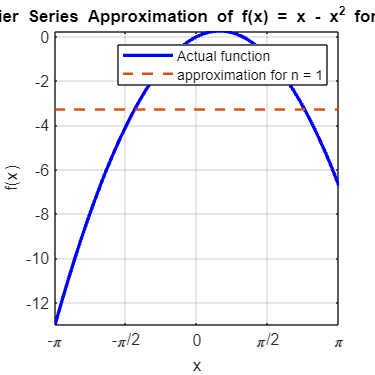

*****************************************************************************


Approximation of f(x) for n = 2


$$4\,\cos\left(x\right)+2\,\sin\left(x\right)-\frac{\pi^{2}}{3}$$

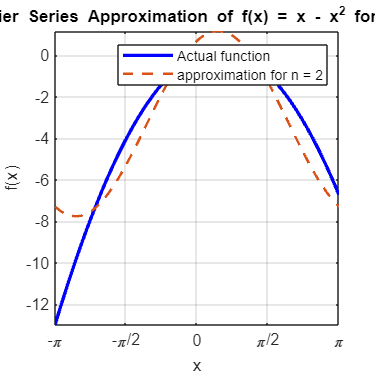

*****************************************************************************


Approximation of f(x) for n = 3


$$4\,\cos\left(x\right)-\sin\left(2\,x\right)-\cos\left(2\,x\right)+2\,\sin\left(x\right)-\frac{\pi^{2}}{3}$$

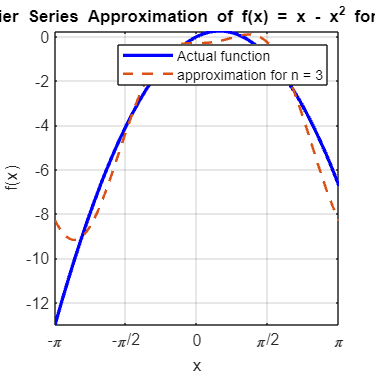

*****************************************************************************


Approximation of f(x) for n = 4


$$\frac{4\,\cos\left(3\,x\right)}{9}-\cos\left(2\,x\right)-\sin\left(2\,x\right)+\frac{2\,\sin\left(3\,x\right)}{3}+4\,\cos\left(x\right)+2\,\sin\left(x\right)-\frac{\pi^{2}}{3}$$

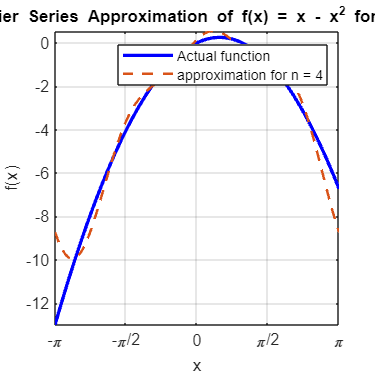

*****************************************************************************


Approximation of f(x) for n = 5


$$\frac{4\,\cos\left(3\,x\right)}{9}-\cos\left(2\,x\right)-\frac{\cos\left(4\,x\right)}{4}-\sin\left(2\,x\right)+\frac{2\,\sin\left(3\,x\right)}{3}-\frac{\sin\left(4\,x\right)}{2}+4\,\cos\left(x\right)+2\,\sin\left(x\right)-\frac{\pi^{2}}{3}$$

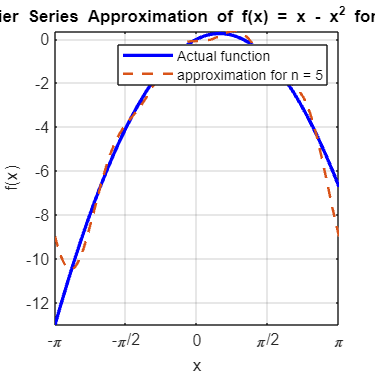

*****************************************************************************


Approximation of f(x) for n = 6


$$\frac{4\,\cos\left(3\,x\right)}{9}-\cos\left(2\,x\right)-\frac{\cos\left(4\,x\right)}{4}+\frac{4\,\cos\left(5\,x\right)}{25}-\sin\left(2\,x\right)+\frac{2\,\sin\left(3\,x\right)}{3}-\frac{\sin\left(4\,x\right)}{2}+\frac{2\,\sin\left(5\,x\right)}{5}+4\,\cos\left(x\right)+2\,\sin\left(x\right)-\frac{\pi^{2}}{3}$$

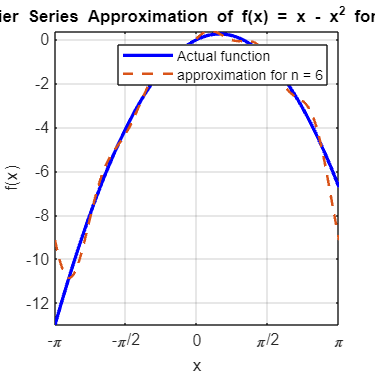

*****************************************************************************



approximation = a0/2;

for k = 1:n

    approximation;
    fprintf('Approximation of f(x) for n = %d\n',k)
    disp(approximation)
    figure('Position', [100, 100, 300, 300]); % Create a new figure for each plot

    % Plot the actual function and Fourier series approximation
    fplot(f,[L,U],'b','LineWidth',2);
    hold on;
    fplot(approximation,[L,U],'LineWidth',1.5, 'LineStyle', '--');
    hold off;
    xlabel('x');

    vec= linspace(lb, ub, 5); % depending the gap required decide the spacing
    tick_labels = string(vec);

    % Replace "pi" with the LaTeX representation of the Greek letter pi
    tick_labels = replace(tick_labels, "pi", "\pi");
    
    xticks(linspace(L, U, 5)); %numel is like len() in python
    xticklabels(tick_labels);

    ylabel('f(x)');
    title(['Fourier Series Approximation of f(x) = ',char(f),' for n = ',num2str(k)]);
    legend('Actual function',['approximation for n = ',num2str(k)]);
    grid on;
    hold off;

    disp('*****************************************************************************')

    approximation = approximation + a(k)*cos(k*x) + b(k)*sin(k*x);
    
end